# **Matlab&Simulink 사용법**

matlab function 또는 simulink block을 사용하는 방법을 설명한다.

## Motor Control

clear all;close all;clc

### 상태방정식 -> 전달함수 변환

시스템의 상태공간 표현식을 이에 상응하는 전달함수로 변환화여 step응답을 확인한다.

- 입력값이 1개인 경우 ss2tf() 함수에 상태벡터(A,B,C,D)만 입력

- 입력값이 여러개 있는 시스템의 경우 ni를 입력하여, ni번째 입력값에 단위 임펄스를 가하여 그 결과로 발생하는 전달함수를 반환

- 연속시스템이면 라플라스 반환, 이산시스템이면 Z변환 전달함수 반환

A=[0 1 0;0 0 1;-18 -15 -2];
B=[0;0;1];
C=[1 0 0];
D=0;
[num,den] = ss2tf(A,B,C,D);
% [num,den] = ss2tf(A,B,C,D,ni)
sys_tf = tf(num,den)


sys_tf =
 
             1
  -----------------------
  s^3 + 2 s^2 + 15 s + 18
 
Continuous-time transfer function.



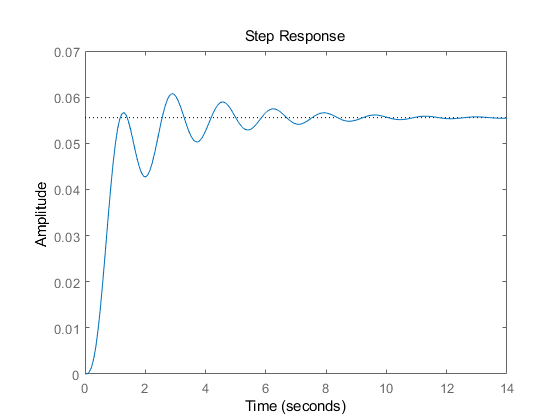

step(sys_tf)

### 전달함수 -> 상태방정식 변환

시스템의 전달함수를 상태방정식으로 변환하여 step응답을 확인한다.

[A_,B_,C_,D_] = tf2ss(num,den);
plant = ss(A_,B_,C_,D_,0.001)


plant =
 
  A = 
        x1   x2   x3
   x1   -2  -15  -18
   x2    1    0    0
   x3    0    1    0
 
  B = 
       u1
   x1   1
   x2   0
   x3   0
 
  C = 
       x1  x2  x3
   y1   0   0   1
 
  D = 
       u1
   y1   0
 
Sample time: 0.001 seconds
Discrete-time state-space model.



eig(A_)                          % Plant 극점(안정도) 확인

ans =   -0.3607 + 3.7346i
  -0.3607 - 3.7346i
  -1.2786 + 0.0000i


step(ss(A_,B_,C_,D_))

### 상태방정식 Continuous -> Discrete 변환

c2d()함수를 이용하여 Continuous상태방정식을 Discrete상태방정식으로 직접 변환한다.

step(ss(A,B,C,D))               % 상태방정식 step응답 확인
hold on;
dt=0.001;                       % sampling 주파수를 1s로 크게해서 이산화 여부 확인
d_sys = c2d(ss(A,B,C,D),dt)    % 상태방정식 이산화


d_sys =
 
  A = 
               x1          x2          x3
   x1           1       0.001   4.997e-07
   x2  -8.994e-06           1    0.000999
   x3    -0.01798    -0.01499       0.998
 
  B = 
              u1
   x1  1.666e-10
   x2  4.997e-07
   x3   0.000999
 
  C = 
       x1  x2  x3
   y1   1   0   0
 
  D = 
       u1
   y1   0
 
Sample time: 0.001 seconds
Discrete-time state-space model.



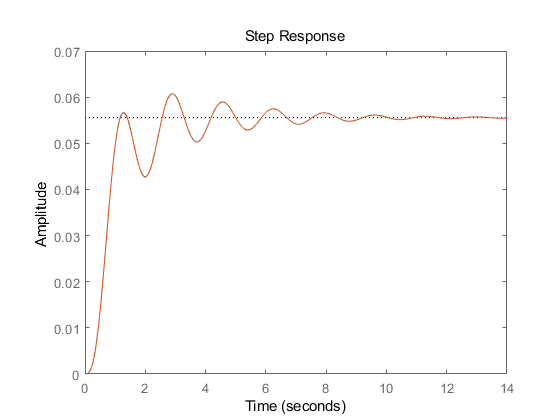

step(d_sys)                     % 이산 상태방정식 step응답 확인

## Plant 정의

clear all;close all;clc


sys1_tf =
 
    1
  -----
  s + 1
 
Continuous-time transfer function.



A=[-2 -15 -18; 1 0 0; 0 1 0];


sys2_tf =
 
  2
 
Static gain.



B=[1;0;0];


sys_tf =
 
    1
  -----
  s + 3
 
Continuous-time transfer function.



C=[0 0 1];
D=0;

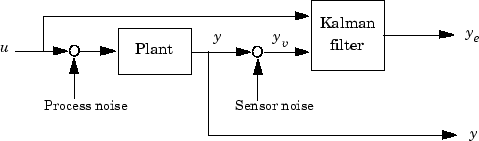

### Plant without noise

노이즈를 고려하지 않을 때 $u\left\lbrack n\right\rbrack$이 입력되고, $y\left\lbrack n\right\rbrack$이 출력되는 상태방정식은 다음과 같다.

plant = ss(A,B,C,D,-1,'inputname',{'u'},'outputname','y');


sys_tf =
 
  2 s + 3
  -------
   s + 1
 
Continuous-time transfer function.



### Plant with w

입력$u\left\lbrack n\right\rbrack$에 프로세스 노이즈$w\left\lbrack n\right\rbrack$가 유입될 때 $y\left\lbrack n\right\rbrack$이 출력되는 이산 Plant 상태방정식은 다음과 같다.


$$\begin{array}{l}
x\left\lbrack n+1\right\rbrack =\mathit{Ax}\left\lbrack n\right\rbrack +B\left(u\left\lbrack n\right\rbrack +w\left\lbrack n\right\rbrack \right)\;\;\to \;\;x\left\lbrack n+1\right\rbrack =\mathit{Ax}\left\lbrack n\right\rbrack +\left\lbrack \begin{array}{cc}
B & B
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
u\left\lbrack n\right\rbrack \\
w\left\lbrack n\right\rbrack 
\end{array}\right\rbrack \\
y\left\lbrack n\right\rbrack =\mathit{Cx}\left\lbrack n\right\rbrack 
\end{array}$$


ss()함수에 '-1(sample time unspecified)'을 인자로 주어 이산 상태방정식 Plant를 정의한다.

plant_w = ss(A,[B B],C,D,-1,'inputname',{'u' 'w'},'outputname','y');

### Plant with w&v

입력$u\left\lbrack n\right\rbrack$에 프로세스 노이즈$w\left\lbrack n\right\rbrack$가 유입되고, 출력 $y\left\lbrack n\right\rbrack$에 측정노이즈 $v\left\lbrack n\right\rbrack$이 추가되어 $y_v \left\lbrack n\right\rbrack$이 출력되는 상태방정식은 다음과 같다.

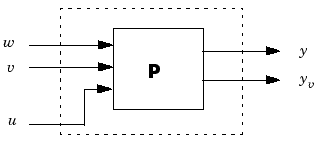,  $\begin{array}{l}
y_v \left\lbrack n\right\rbrack =y\left\lbrack n\right\rbrack +v\left\lbrack n\right\rbrack \\
y_v \left\lbrack n\right\rbrack =\mathit{Cx}\left\lbrack n\right\rbrack +v\left\lbrack n\right\rbrack 
\end{array}$


$$\begin{array}{l}
\dot{x} =\left\lbrack \begin{array}{ccc}
\cdot  & \cdot  & \cdot \\
\cdot  & A & \cdot \\
\cdot  & \cdot  & \cdot 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
\cdot \\
B\\
\cdot 
\end{array}\right\rbrack u\\
y=\left\lbrack \begin{array}{ccc}
\cdot  & C & \cdot 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
D
\end{array}\right\rbrack u
\end{array}$$
       
$$\to$$
     
$$\begin{array}{l}
\dot{x} =\left\lbrack \begin{array}{ccc}
\cdot  & \cdot  & \cdot \\
\cdot  & A & \cdot \\
\cdot  & \cdot  & \cdot 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 
\end{array}\right\rbrack +\left\lbrack \begin{array}{ccc}
\cdot  & \cdot  & 0\\
\cdot  & B & 0\\
\cdot  & \cdot  & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
u\\
w\\
v
\end{array}\right\rbrack \\
y=\left\lbrack \begin{array}{c}
y\\
y_v 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
1 & 0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 
\end{array}\right\rbrack +\left\lbrack \begin{array}{ccc}
0 & 0 & 0\\
0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
u\\
w\\
v
\end{array}\right\rbrack 
\end{array}$$


plant_wv = ss(A,[B B 0*B],[C;C],[0 0 0;0 0 1],-1,'inputname',{'u' 'w' 'v'},'outputname',{'y' 'yv'});

## 전달함수 합성

### Feedback

$G=\frac{1}{s+1}$이고, $H=2$인 경우


$$\begin{array}{l}
e=t-\mathit{Hv}\\
v=\mathit{eG}\\
v=\left(t-\mathit{Hv}\right)G=\mathit{Gt}-\mathit{GHv}\\
\left(1+\mathit{GH}\right)v=\mathit{Gt}\\
\frac{v}{t}=\frac{G}{1+\mathit{GH}}=\frac{1}{\left(1/G\right)+H}=\frac{1}{\left(s+1\right)+2}=\frac{1}{s+3}
\end{array}$$


sys1_tf=tf(1, [1 1])
sys2_tf=tf(2)
sys_tf=feedback(sys1_tf, sys2_tf, -1)

### Parallel


$$\frac{1}{s+1}+2=\frac{1+2s+2}{s+1}=\frac{2s+3}{s+1}$$


sys_tf=parallel(sys1_tf, sys2_tf)

## Stateflow Software Logic

## script

### m-file 내에서 함수 사용

m파일 내에서 함수를 만들고, 동일한 m파일에서 스크립트를 실행해 함수를 호출할 경우 line by line(F9)으로 스크립트를 실행하면 함수를 인식하지 못하고, 전체실행(F5)로 스크립트를 실행해야 함수를 인식할 수 있다.x = 3;

y = 2;
z = perm(x,y)


function p = perm(n,r)
    p = fact(n)*fact(n-r);
end

### Block 단위 주석처리

'%{'와 '%}'로 코드를 감싸면 block 단위로 주석을 처리할 수 있다.

%{
u=[0 1]';
for t=2:TMAX
    A=[[1 dt ]; ...
    [0 (1.0-(k/m)*dt) ]];
    B=[[1 0 ]; ...
    x(:,t) = A*x(:,t-1) + B*u;
end
subplot(2,1,1); plot(x(1,:)); hold on;
subplot(2,1,2); plot(x(2,:)); hold on;
%}

## < EOD >